# Plot residual wavefields

## Introduction

Plot wavefields corresponding to different velocity models

"I think this manuscript is worth publishing in our Journal, I just have one comment. 

Please provide the shot gather of Figure 3c 3d and 3e, then compare them with the original shot gather in Figure 2. 

I want to know that if their residual with Figure 2 are (reflection and diffraction)`, (diffraction wave) and (zero).

**Author**: Ivan Abakumov

**Publication date**: 19th June 2019

**E-mail**: [abakumov_ivan@mail.ru](mailto:abakumov_ivan@mail.ru)

## Add MLIB library

clear; close all; clc;
mlibfolder = '/home/ivan/Desktop/MLIB';
path(path, mlibfolder);
add_mlib_path;

## Result of tomography and FWI

INV_settings;

resultfolder = [mlibfolder '/Examples/Paper_Role_of_diffractions_in_velocity_model_building/result'];
% Tomography
fname_dV = [resultfolder '/TOMO/TOMO_First_dv_111.mat'];
dV = zeros(G.nx, G.nz); 
dV(target.xx,target.zz) = MLD(fname_dV); 
velmod.tomo = bvelmod + dV;

% FWI, diving only
fname_dV = [resultfolder '/FWI_diving_only/FWI_First_dv_55.mat'];
dV = zeros(G.nx, G.nz); 
dV(target.xx,target.zz) = MLD(fname_dV); 
velmod.fwi1 = bvelmod + dV;

% FWI, diving and reflections
fname_dV = [resultfolder '/FWI_diving_ref/FWI_First_dv_59.mat'];
dV = zeros(G.nx, G.nz); 
dV(target.xx,target.zz) = MLD(fname_dV); 
velmod.fwi2 = bvelmod + dV;

% FWI, full wavefield
fname_dV = [resultfolder '/FWI_diving_ref_diff/FWI_First_dv_59.mat'];
dV = zeros(G.nx, G.nz); 
dV(target.xx,target.zz) = MLD(fname_dV); 
velmod.fwi3 = bvelmod + dV;

## Calculate traveltimes of direct waves

tdir = zeros(length(acq.sx), length(acq.rx)); 

for s=1:length(acq.sx)
    S = [acq.sx(s), acq.sz(s)];
    tti = FSM2D(Gold,S,bvelmod);
    
    for r=1:length(acq.rx)
        tdir(s,r) = tti(acq.grx(r),acq.grz(r));
    end
end

tdir = round((tdir)/G.dt + 1) + 25; 


## Calculate traveltimes of diffraction events

S1 = [2500, 500];
S2 = [2500, 750];
S3 = [3000, 500];

tti1 = FSM2D(Gold,S1,mvelmod);
tti2 = FSM2D(Gold,S2,mvelmod);
tti3 = FSM2D(Gold,S3,mvelmod);

tdif1 = zeros(length(acq.sx), length(acq.rx)); 
tdif2 = zeros(length(acq.sx), length(acq.rx)); 
tdif3 = zeros(length(acq.sx), length(acq.rx)); 

for s=1:length(acq.sx)
    for r=1:length(acq.rx)
        tdif1(s,r) = tti1(acq.gsx(s),acq.gsz(s)) + tti1(acq.grx(r),acq.grz(r));
        tdif2(s,r) = tti2(acq.gsx(s),acq.gsz(s)) + tti2(acq.grx(r),acq.grz(r));
        tdif3(s,r) = tti3(acq.gsx(s),acq.gsz(s)) + tti3(acq.grx(r),acq.grz(r));
    end
end


## Make sin filter

filter = ones(1,101);
filter(1:26) = sin(linspace(0, pi/2, 26)).^2;
filter(76:101) = sin(linspace(pi/2, 0, 26)).^2;


shotnum = [8 16 24]

shotnum =      8    16    24


fpeak = 8;
% tomo
[f10,~,~] = Get_FD_forward(G, acq, shotnum, fpeak, velmod.tomo);

Constant dencity acoustic modeling: rho=const, vs=0.
el2d will be executed with 8 threads.
Minimum number of grid points per shortest wavelength: 6.49778 >= 2.
Stability parameter: 1.28876 > 1.
Computing wavefields...Dimensions for output arrays: 501 x 401 x 800 x 3


Stability parameter: 1.28875 > 1.
Parameters:
nout = 3;
nx = 501; nz = 401;
nxl = 501; nzl = 401;
nsht = 3; nb = 0; ngob=30;
nt = 800; dt = 0.002750; fpeak = 8.000000;
dx = 12.500000; dz = 12.500000;
bc = 0, stype = 0; wtype = 0; atype=1;
sxi[0] = 206; szi[0] = 120;
lxi[0] = 0; lzi[0] = 0;
Calling master routine from gateway routine...
Master routine terminated successfully.
Done. Elapsed time is 104.227737 seconds.


wavefield.tomo = zeros(length(acq.rx), G.nt,length(shotnum));
for s=1:length(shotnum) 
    for i=1:length(acq.rx)
        wavefield.tomo(i,:,s) = squeeze(f10(acq.grx(i),acq.grz(i),:,s));
    end
end
clear f10

% fwi1
[f10,~,~] = Get_FD_forward(G, acq, shotnum, fpeak, velmod.fwi1);

Constant dencity acoustic modeling: rho=const, vs=0.
el2d will be executed with 8 threads.
Minimum number of grid points per shortest wavelength: 7.27096 >= 2.
Stability parameter: 1.28876 > 1.
Computing wavefields...Dimensions for output arrays: 501 x 401 x 800 x 3


Stability parameter: 1.28875 > 1.
Parameters:
nout = 3;
nx = 501; nz = 401;
nxl = 501; nzl = 401;
nsht = 3; nb = 0; ngob=30;
nt = 800; dt = 0.002750; fpeak = 8.000000;
dx = 12.500000; dz = 12.500000;
bc = 0, stype = 0; wtype = 0; atype=1;
sxi[0] = 206; szi[0] = 120;
lxi[0] = 0; lzi[0] = 0;
Calling master routine from gateway routine...
Master routine terminated successfully.
Done. Elapsed time is 59.909292 seconds.


wavefield.tomo = zeros(length(acq.rx), G.nt,length(shotnum));
for s=1:length(shotnum) 
    for i=1:length(acq.rx)
        wavefield.fwi1(i,:,s) = squeeze(f10(acq.grx(i),acq.grz(i),:,s));
    end
end
clear f10

% fwi2
[f10,~,~] = Get_FD_forward(G, acq, shotnum, fpeak, velmod.fwi2);

Constant dencity acoustic modeling: rho=const, vs=0.
el2d will be executed with 8 threads.
Minimum number of grid points per shortest wavelength: 7.28583 >= 2.
Stability parameter: 1.28876 > 1.
Computing wavefields...Dimensions for output arrays: 501 x 401 x 800 x 3


Stability parameter: 1.28875 > 1.
Parameters:
nout = 3;
nx = 501; nz = 401;
nxl = 501; nzl = 401;
nsht = 3; nb = 0; ngob=30;
nt = 800; dt = 0.002750; fpeak = 8.000000;
dx = 12.500000; dz = 12.500000;
bc = 0, stype = 0; wtype = 0; atype=1;
sxi[0] = 206; szi[0] = 120;
lxi[0] = 0; lzi[0] = 0;
Calling master routine from gateway routine...
Master routine terminated successfully.
Done. Elapsed time is 58.927569 seconds.


wavefield.tomo = zeros(length(acq.rx), G.nt,length(shotnum));
for s=1:length(shotnum) 
    for i=1:length(acq.rx)
        wavefield.fwi2(i,:,s) = squeeze(f10(acq.grx(i),acq.grz(i),:,s));
    end
end
clear f10

% fwi3
[f10,~,~] = Get_FD_forward(G, acq, shotnum, fpeak, velmod.fwi3);

Constant dencity acoustic modeling: rho=const, vs=0.
el2d will be executed with 8 threads.
Minimum number of grid points per shortest wavelength: 7.25862 >= 2.
Stability parameter: 1.28876 > 1.
Computing wavefields...Dimensions for output arrays: 501 x 401 x 800 x 3


Stability parameter: 1.28875 > 1.
Parameters:
nout = 3;
nx = 501; nz = 401;
nxl = 501; nzl = 401;
nsht = 3; nb = 0; ngob=30;
nt = 800; dt = 0.002750; fpeak = 8.000000;
dx = 12.500000; dz = 12.500000;
bc = 0, stype = 0; wtype = 0; atype=1;
sxi[0] = 206; szi[0] = 120;
lxi[0] = 0; lzi[0] = 0;
Calling master routine from gateway routine...
Master routine terminated successfully.
Done. Elapsed time is 59.724327 seconds.


wavefield.tomo = zeros(length(acq.rx), G.nt,length(shotnum));
for s=1:length(shotnum) 
    for i=1:length(acq.rx)
        wavefield.fwi3(i,:,s) = squeeze(f10(acq.grx(i),acq.grz(i),:,s));
    end
end
clear f10

% tomo
[f10,~,~] = Get_FD_forward(G, acq, shotnum, fpeak, mvelmod);

Constant dencity acoustic modeling: rho=const, vs=0.
el2d will be executed with 8 threads.
Minimum number of grid points per shortest wavelength: 7.5 >= 2.
Stability parameter: 1.28876 > 1.
Computing wavefields...Dimensions for output arrays: 501 x 401 x 800 x 3


Stability parameter: 1.28875 > 1.
Parameters:
nout = 3;
nx = 501; nz = 401;
nxl = 501; nzl = 401;
nsht = 3; nb = 0; ngob=30;
nt = 800; dt = 0.002750; fpeak = 8.000000;
dx = 12.500000; dz = 12.500000;
bc = 0, stype = 0; wtype = 0; atype=1;
sxi[0] = 206; szi[0] = 120;
lxi[0] = 0; lzi[0] = 0;
Calling master routine from gateway routine...
Master routine terminated successfully.
Done. Elapsed time is 57.201082 seconds.


wavefield.true = zeros(length(acq.rx), G.nt,length(shotnum));
for s=1:length(shotnum) 
    for i=1:length(acq.rx)
        wavefield.true(i,:,s) = squeeze(f10(acq.grx(i),acq.grz(i),:,s));
    end
end

## Plot figures for paper

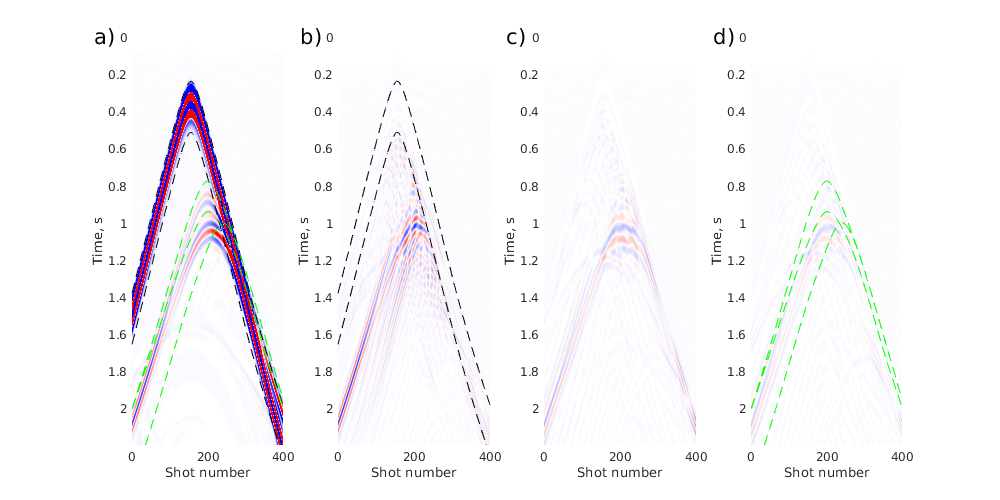


tmin = max(1,tdir(shotnum(1),:))*G.dt;
tmax = min(G.nt, tdir(shotnum(1),:) + 100)*G.dt;


figure(833)
tshift = 0.0825; 
fig = figure('Position', [1 1 1000 500]);
amp = 0.000005;

subplot(1,4,1)
pcolor(acq.rx/G.dx, G.tt, wavefield.true(:,:,1)')
shading interp
hold on 
plot(acq.rx/G.dx, tmin, '--k')
plot(acq.rx/G.dx, tmax, '--k')
plot(1:401, tdif1(shotnum(1),:)+tshift, '--g');
plot(1:401, tdif2(shotnum(1),:)+tshift, '--g');
plot(1:401, tdif3(shotnum(1),:)+tshift, '--g');
set(gca,'YDir','reverse')
caxis([-amp amp])
ylabel('Time, s');
xlabel('Shot number');
text(-100,0,'a)','FontSize',16, 'Color', 'k');

subplot(1,4,2)
pcolor(acq.rx/G.dx, G.tt, wavefield.true(:,:,1)' - wavefield.fwi1(:,:,1)')
shading interp
set(gca,'YDir','reverse')
hold on 
plot(acq.rx/G.dx, tmin, '--k')
plot(acq.rx/G.dx, tmax, '--k')
caxis([-amp amp])
ylabel('Time, s');
xlabel('Shot number');
text(-100,0,'b)','FontSize',16, 'Color', 'k');

subplot(1,4,3)
pcolor(acq.rx/G.dx, G.tt, wavefield.true(:,:,1)' - wavefield.fwi2(:,:,1)')
shading interp
set(gca,'YDir','reverse')
caxis([-amp amp])
ylabel('Time, s');
xlabel('Shot number');
text(-100,0,'c)','FontSize',16, 'Color', 'k');


subplot(1,4,4)
pcolor(acq.rx/G.dx, G.tt, wavefield.true(:,:,1)' - wavefield.fwi3(:,:,1)')
shading interp
set(gca,'YDir','reverse')
caxis([-amp amp])
ylabel('Time, s');
xlabel('Shot number');
colormap(makeColorMap([0 0 1],[1 1 1],[1 0 0],100));
text(-100,0,'d)','FontSize',16, 'Color', 'k');
hold on
plot(1:401, tdif1(shotnum(1),:)+tshift, '--g');
plot(1:401, tdif2(shotnum(1),:)+tshift, '--g');
plot(1:401, tdif3(shotnum(1),:)+tshift, '--g');

%colormap('gray')



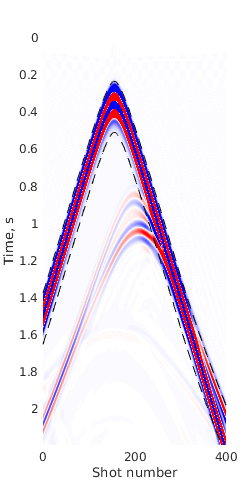

tshift = 0.0825; 
amp = 0.000005;

figure(411)
fig = figure('Position', [1 1 250 500]);
pcolor(acq.rx/G.dx, G.tt, wavefield.true(:,:,1)')
shading interp
hold on 
plot(acq.rx/G.dx, tmin, '--k')
plot(acq.rx/G.dx, tmax, '--k')
%plot(1:401, tdif1(shotnum(1),:)+tshift, '--g');
%plot(1:401, tdif2(shotnum(1),:)+tshift, '--g');
%plot(1:401, tdif3(shotnum(1),:)+tshift, '--g');
set(gca,'YDir','reverse')
caxis([-amp amp])
ylabel('Time, s');
xlabel('Shot number');
%text(-100,0,'a)','FontSize',16, 'Color', 'k');
colormap(makeColorMap([0 0 1],[1 1 1],[1 0 0],100));

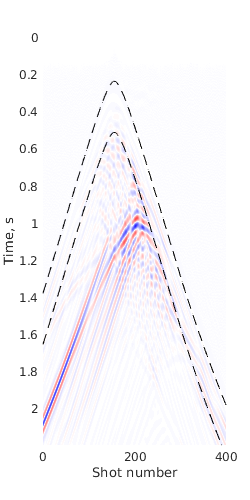


figure(42)
fig = figure('Position', [1 1 250 500]);
pcolor(acq.rx/G.dx, G.tt, wavefield.true(:,:,1)' - wavefield.fwi1(:,:,1)')
shading interp
set(gca,'YDir','reverse')
hold on 
plot(acq.rx/G.dx, tmin, '--k')
plot(acq.rx/G.dx, tmax, '--k')
caxis([-amp amp])
ylabel('Time, s');
xlabel('Shot number');
%text(-100,0,'b)','FontSize',16, 'Color', 'k');
colormap(makeColorMap([0 0 1],[1 1 1],[1 0 0],100));

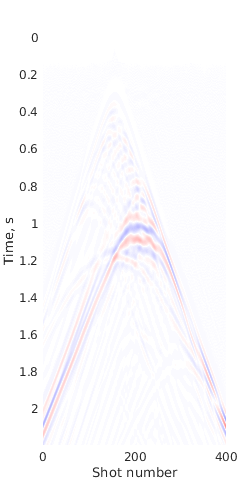


figure(43)
fig = figure('Position', [1 1 250 500]);
pcolor(acq.rx/G.dx, G.tt, wavefield.true(:,:,1)' - wavefield.fwi2(:,:,1)')
shading interp
set(gca,'YDir','reverse')
caxis([-amp amp])
ylabel('Time, s');
xlabel('Shot number');
%text(-100,0,'c)','FontSize',16, 'Color', 'k');
colormap(makeColorMap([0 0 1],[1 1 1],[1 0 0],100));

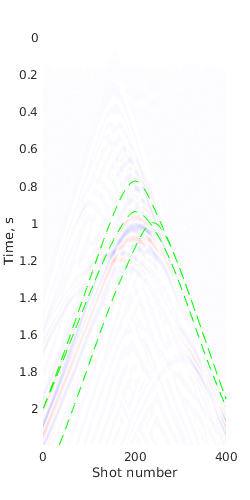



figure(44)
fig = figure('Position', [1 1 250 500]);
pcolor(acq.rx/G.dx, G.tt, wavefield.true(:,:,1)' - wavefield.fwi3(:,:,1)')
shading interp
set(gca,'YDir','reverse')
caxis([-amp amp])
ylabel('Time, s');
xlabel('Shot number');
colormap(makeColorMap([0 0 1],[1 1 1],[1 0 0],100));
%text(-100,0,'d)','FontSize',16, 'Color', 'k');
hold on
plot(1:401, tdif1(shotnum(1),:)+tshift, '--g');
plot(1:401, tdif2(shotnum(1),:)+tshift, '--g');
plot(1:401, tdif3(shotnum(1),:)+tshift, '--g');

%colormap('gray')